
%load invKineObject.mat inv_kine_object;
load fwdKineObject.mat fwd_kine_object;
load plant_specs.mat dims motor fwdKineSys invKineSys funcs;

grad = struct with fields:
    l1: [1×1 struct]
    l2: [1×1 struct]


grad = struct with fields:
    l1: [1×1 struct]
    l2: [1×1 struct]


grad = struct with fields:
    l1: [1×1 struct]
    l2: [1×1 struct]


grad = struct with fields:
    l1: [1×1 struct]
    l2: [1×1 struct]


%load boundaryResults.mat boundaryObject;

fwdLookupObject = createLookupsFwd(points_grid_object_fwd, fwd_kine_object)

fwdLookupObject = struct with fields:
    points_grid_object: [1×1 struct]
       fwd_kine_lookup: [1×1 struct]
           grad_lookup: [1×1 struct]


invLookupObject = createLookupsInv(points_grid_object_inv, inv_kine_object)

invLookupObject = struct with fields:
    points_grid_object: [1×1 struct]
       inv_kine_lookup: [1×1 struct]
           grad_lookup: [1×1 struct]


current_p = fwdKine([dims.maxStringLength-.1 dims.maxStringLength-.1], fwdKineSys);
current_p = [current_p.x, current_p.y]

current_p =     0.5969   -1.0372


current_l = invKine(current_p, invKineSys);
current_l = [current_l.l1 current_l.l2]

current_l =     1.1573    1.1573



target_p = current_p+[.25 .5];

boundaryObject.isInBoundary(target_p)

ans = logical
   1


r = (target_p-current_p)/norm(target_p-current_p); % Return unit vector pointing to target
current_grad.l1.x = invLookupObject.grad_lookup.l1.x(current_p);
current_grad.l1.y = invLookupObject.grad_lookup.l1.y(current_p);
current_grad.l2.x = invLookupObject.grad_lookup.l2.x(current_p);
current_grad.l2.y = invLookupObject.grad_lookup.l2.y(current_p);

direction.l1 = dot([current_grad.l1.x current_grad.l1.y],r);
direction.l2 = dot([current_grad.l2.x current_grad.l2.y],r);

steps = funcs.tfLengthsToStepsDelta([direction.l1 direction.l2]);
min_step = 10;
scaled_steps = round(min_step*steps./min(steps));
current_l = current_l+funcs.tfStepsToLengthsDelta(scaled_steps)

current_l =     1.1549    1.1528


current_p = [fwdLookupObject.fwd_kine_lookup.x(current_l), fwdLookupObject.fwd_kine_lookup.y(current_l)]

current_p =     0.5988   -1.0333


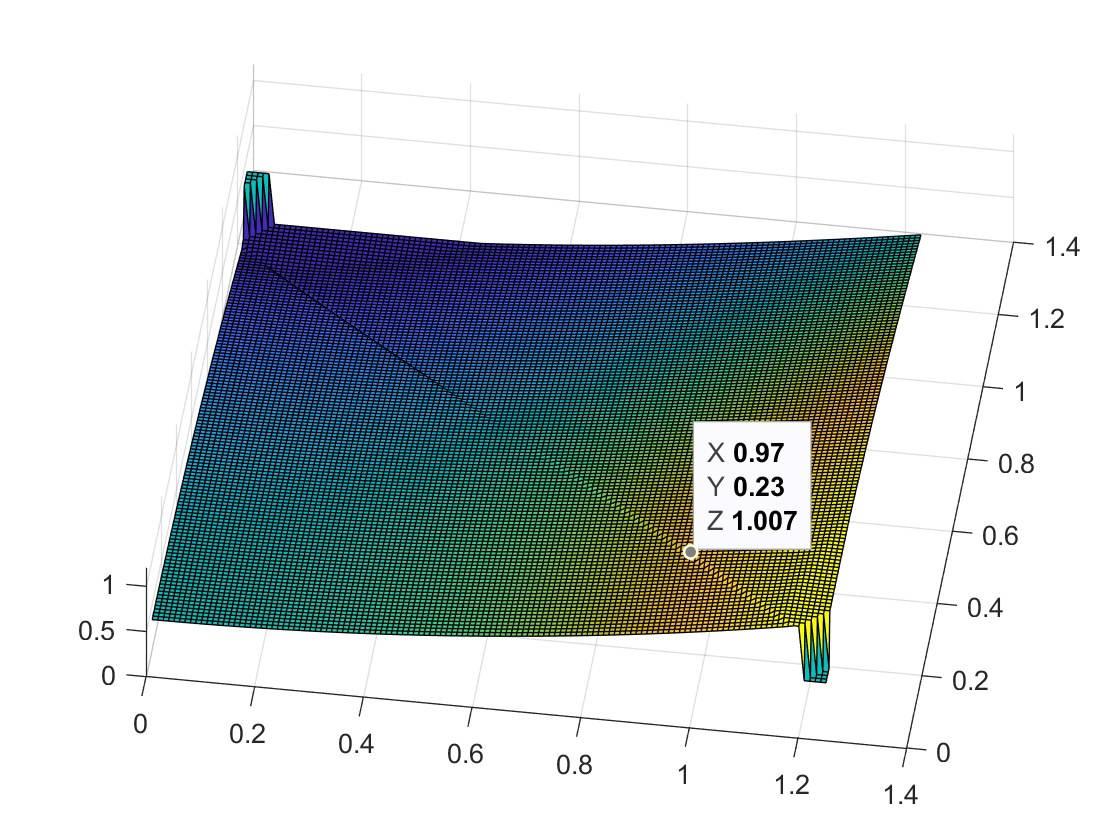

surf(points_grid_object_fwd.l1_list,points_grid_object_fwd.l2_list,fwdLookupObject.fwd_kine_lookup.x(points_grid_object_fwd.l1_list, points_grid_object_fwd.l2_list))